Example 6.3 in book (Picker thyroid phantom)

## Reading img

img = imread('garments.tif');

## False coloring

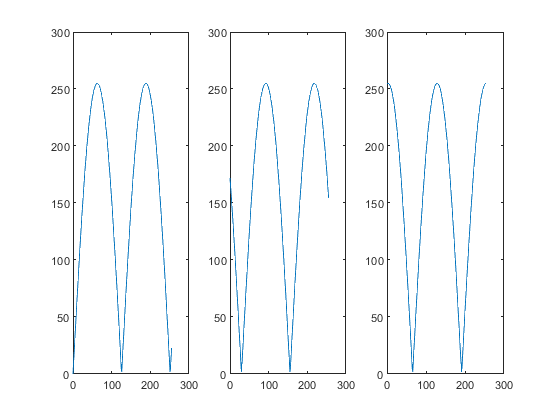

r_pha = 0;
g_pha = 2.4;
b_pha = 1.5;
r_freq = 0.025;
g_freq = 0.025;
b_freq = 0.025;

img = double(img);
transform = @(x, phase, frequency) 255 * abs(sin(phase + frequency*x));

colored_img = uint8(cat(3, ...
    transform(img(:,:,1), r_pha, r_freq), ...
    transform(img(:,:,2), g_pha, g_freq), ...
    transform(img(:,:,3), b_pha, b_freq)));
img = uint8(img);

figure(1);
plot_range = 0:1:255;
subplot(1, 3, 1); plot(plot_range, transform(plot_range, r_pha, r_freq));
subplot(1, 3, 2); plot(plot_range, transform(plot_range, g_pha, g_freq));
subplot(1, 3, 3); plot(plot_range, transform(plot_range, b_pha, b_freq));

## Plotting

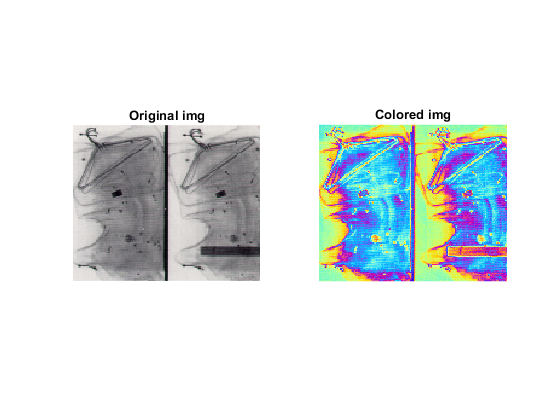

figure(2);
subplot(1, 2, 1); imshow(img);          title('Original img');
subplot(1, 2, 2); imshow(colored_img);  title('Colored img');